# Robot Control Project

## Homogeneous Transformation Matrices

syms q1 q2 q3 q4 q5 q6 
syms L1a L2a L3a L4a
syms L2w L3w L4w
pi  = sym(pi)

$$pi = \pi$$


assume(L1a, 'positive')
assume(L2a, 'positive')
assume(L3a, 'positive')
assume(L4a, 'positive')
% assume(L2w, 'positive')
% assume(L3w, 'positive')
% assume(L4w, 'positive')

H_0_1 = trotz(q1)*transl([0 0 L1a])*trotx(pi/2)

$$H\_0\_1 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & 0\\ 0 & 1 & 0 & \mathrm{L1a}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


H_1_2 = trotz(q2+atan(L2a/L3a)+pi)*transl([sqrt(L2a^2 + L3a^2) 0 0])*trotx(pi)

$$H\_1\_2 = \begin{array}{l} \left(\begin{array}{cccc} -\sigma_{1} & -\sin\left(q_{2}+\mathrm{atan}\left(\frac{\mathrm{L2a}}{\mathrm{L3a}}\right)\right) & 0 & -\sigma_{1}\,\sqrt{{\mathrm{L2a}}^{2}+{\mathrm{L3a}}^{2}}\\ -\sin\left(q_{2}+\mathrm{atan}\left(\frac{\mathrm{L2a}}{\mathrm{L3a}}\right)\right) & \sigma_{1} & 0 & -\sin\left(q_{2}+\mathrm{atan}\left(\frac{\mathrm{L2a}}{\mathrm{L3a}}\right)\right)\,\sqrt{{\mathrm{L2a}}^{2}+{\mathrm{L3a}}^{2}}\\ 0 & 0 & -1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{2}+\mathrm{atan}\left(\frac{\mathrm{L2a}}{\mathrm{L3a}}\right)\right) \end{array}$$


H_2_3 = trotz(q3+pi)*transl([L4a/sqrt(2) 0 0])*trotx(pi)

$$H\_2\_3 = \left(\begin{array}{cccc} -\cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & -\frac{\sqrt{2}\,\mathrm{L4a}\,\cos\left(q_{3}\right)}{2}\\ -\sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & -\frac{\sqrt{2}\,\mathrm{L4a}\,\sin\left(q_{3}\right)}{2}\\ 0 & 0 & -1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


H_3_4 = trotz(q4+pi)*transl([(L4a/sqrt(2))+L2w*sqrt(2) 0 0])*trotx(pi/4)

$$H\_3\_4 = \begin{array}{l} \left(\begin{array}{cccc} -\cos\left(q_{4}\right) & \frac{\sqrt{2}\,\sin\left(q_{4}\right)}{2} & -\frac{\sqrt{2}\,\sin\left(q_{4}\right)}{2} & -\cos\left(q_{4}\right)\,\sigma_{1}\\ -\sin\left(q_{4}\right) & -\frac{\sqrt{2}\,\cos\left(q_{4}\right)}{2} & \frac{\sqrt{2}\,\cos\left(q_{4}\right)}{2} & -\sin\left(q_{4}\right)\,\sigma_{1}\\ 0 & \frac{\sqrt{2}}{2} & \frac{\sqrt{2}}{2} & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}\,\mathrm{L4a}}{2}+\sqrt{2}\,\mathrm{L2w} \end{array}$$


H_4_5 = trotz(q5)*transl([L4w 0 0])*trotx(pi*3/2)

$$H\_4\_5 = \left(\begin{array}{cccc} \cos\left(q_{5}\right) & 0 & -\sin\left(q_{5}\right) & \mathrm{L4w}\,\cos\left(q_{5}\right)\\ \sin\left(q_{5}\right) & 0 & \cos\left(q_{5}\right) & \mathrm{L4w}\,\sin\left(q_{5}\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


H_5_6 = trotz(q6)*transl([L3w 0 0])

$$H\_5\_6 = \left(\begin{array}{cccc} \cos\left(q_{6}\right) & -\sin\left(q_{6}\right) & 0 & \mathrm{L3w}\,\cos\left(q_{6}\right)\\ \sin\left(q_{6}\right) & \cos\left(q_{6}\right) & 0 & \mathrm{L3w}\,\sin\left(q_{6}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


H_0_6 = simplify(H_0_1*H_1_2*H_2_3*H_3_4*H_4_5*H_5_6)


## Forward kinematics:



X = H_0_6(1,4);
Y = H_0_6(2,4);
Z = H_0_6(3,4);

R = H_0_6(1:3,1:3);


## Jacobian matrix:

% En este caso al tener 6 DOF tendremos un jacobiano de 6x6

J(1,1) = diff(X,q1);
J(1,2) = diff(X,q2);
J(1,3) = diff(X,q3);
J(1,4) = diff(X,q4);
J(1,5) = diff(X,q5);
J(1,6) = diff(X,q6);

J(2,1) = diff(Y,q1);
J(2,2) = diff(Y,q2);
J(2,3) = diff(Y,q3);
J(2,4) = diff(Y,q1); % J(2,4) = diff(Y,q1);
J(2,5) = diff(Y,q2); % J(2,5) = diff(Y,q2);
J(2,6) = diff(Y,q3); % J(2,6) = diff(Y,q3);

J(3,1) = diff(Z,q1);
J(3,2) = diff(Z,q2);
J(3,3) = diff(Z,q3);
J(3,4) = diff(Z,q4); % J(3,1) = diff(Z,q1);
J(3,5) = diff(Z,q5); % J(3,2) = diff(Z,q2);
J(3,6) = diff(Z,q6); % J(3,3) = diff(Z,q3);


J   % Jacobiano de Velocidades Lineales 
% Igualar a cero y resolver 


## Circle Drawing

% Robot Object 

D = [2 9 5 5 5 5 5 8];

L1a_val = 0.9 - 0.04*D(2); 
L2a_val = 0.4 + 0.02*D(6); 
L3a_val = 0.4 + 0.01*D(3); 
L4a_val = 0.5 - 0.02*D(7);

% L2w_val = 0.3; 
% L3w_val = 0.2; 
% L4w_val = 0.2;


L(1) = Link('d', L1a_val, 'a', 0,                           'alpha', pi/2, 'offset', 0);
L(2) = Link('d', 0,       'a', - sqrt(L2a_val^2 + L3a_val^2), 'alpha', 0, 'offset', atan2(L2a_val,L3a_val) + pi);
L(3) = Link('d', 0,       'a', L4a_val,             'alpha', 0, 'offset', -atan2(L2a_val,L3a_val) + pi);
%L(4) = Link('d', 0,       'a', (L4a_val/sqrt(2))+L2w_val*sqrt(2), 'alpha', pi/4, 'offset', pi);
%L(5) = Link('d', 0,       'a', L4w_val,     'alpha', pi*3/2, 'offset', 0);
%L(6) = Link('d', 0,       'a', L3w_val,     'alpha', 0,      'offset', 0);
%robot_6dof = SerialLink(L, 'name', 'Robot 6-DOF');
robot_3dof = SerialLink(L, 'name', 'Robot 3-DOF');


disp(robot_3dof);

  SerialLink with properties:

            name: 'Robot 3-DOF'
         gravity: [3×1 double]
            base: [1×1 SE3]
            tool: [1×1 SE3]
    manufacturer: ''
         comment: ''
         plotopt: []
            fast: 1
       interface: []
       ikineType: []
           trail: []
           movie: []
           delay: []
            loop: []
         model3d: []
           faces: []
          points: []
       plotopt3d: []
               n: 3
           links: [1×3 Link]
               T: []
             mdh: 0
          config: 'RRR'
          offset: [0 3.9796 2.3036]
            qlim: [3×2 double]
               d: [0.5400 0 0]
               a: [0 -0.6727 0.4000]
           alpha: [1.5708 0 0]
           theta: []



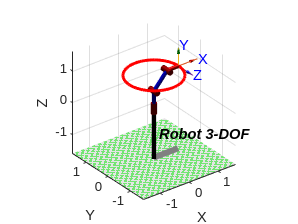



% Trajectory Planning 

q_inicial = [0 0 0];

T_inicial = robot_3dof.fkine(q_inicial);

centro = [0 0 L1a_val + L2a_val];

num_puntos = 100;                   % Número de puntos en el círculo
radio = L3a_val + L4a_val;          % Radio del círculo (en metros)
t = linspace(0, 2*pi, num_puntos);  % Vector de ángulos

x_local = radio * cos(t);
y_local = radio * sin(t);

path_X = centro(1) + radio * cos(t); % (1x100)
path_Y = centro(2) + radio * sin(t); % (1x100)
path_Z = ones(1, num_puntos) * centro(3); % (1x100)

puntos_camino = [path_X; 
                 path_Y; 
                 path_Z];

%mstraj 

T_path = transl(puntos_camino');


% Simulacion y Cinematica Inversa 

mascara = [1 1 1 0 0 0];

q_path = robot_3dof.ikine(T_path, 'q0', q_inicial, 'mask', mascara);

figure;
robot_3dof.plot(q_path, 'trail', {'r', 'LineWidth', 2});

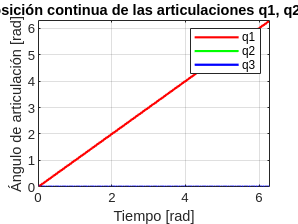


% Hacer continua la trayectoria de q
q_continuo = unwrap(q_path, [], 1);  % unwrap a lo largo de las filas

figure;
plot(t, q_continuo(:,1), 'r', 'LineWidth', 1.5); hold on;
plot(t, q_continuo(:,2), 'g', 'LineWidth', 1.5);
plot(t, q_continuo(:,3), 'b', 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [rad]');
ylabel('Ángulo de articulación [rad]');
title('Posición continua de las articulaciones q1, q2, q3');
legend('q1', 'q2', 'q3');